clear, clc, close
load RailProps.mat

tf = 1;
dt = 0.001;
t = 0:dt:tf;

% Indentation
delta = sin(pi*t);
deltadot = diff(delta);
deltadot = [deltadot deltadot(end)];
deltadotn = deltadot(1);

% Lateral displacement (sliding)
ulat = 0.2*sin(4*pi*t);
udotlat = diff(ulat)/dt;
udotlat = [udotlat udotlat(end)];

cr = 1.0;
RyWheel = 1;
RyRail = 1;

normalforce = zeros(1, length(t));
a = zeros(1, length(t));
b = zeros(1, length(t));
tangentforce_1 = zeros(1, length(t));
tangentforce_2 = zeros(1, length(t));

for ii = 1:length(t)
    % NormalForce(ind, deltadot, RailProps, deltadotn, cr, RyWheel, RyRail)
    [normalforce(ii), a(ii), b(ii)] = NormalForce( ...
        delta(ii), deltadot(ii), RailProps, deltadotn, cr, RyWheel, RyRail);

    % Compute the tangential creep force
    tangentforce_1(ii) = creep_forces( ...
        a(ii), b(ii), normalforce(ii), udotlat(ii), 0, 10, RailProps, "kalker");

    tangentforce_2(ii) = creep_forces( ...
        a(ii), b(ii), normalforce(ii), udotlat(ii), 0, 10, RailProps, "carter");
end



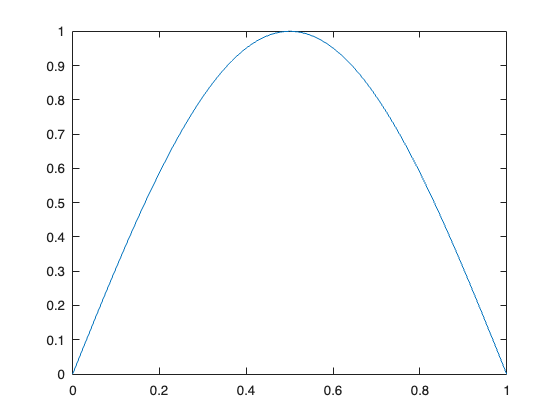

f1 = figure(1); f1.Theme = "Light";
plot(t, delta)

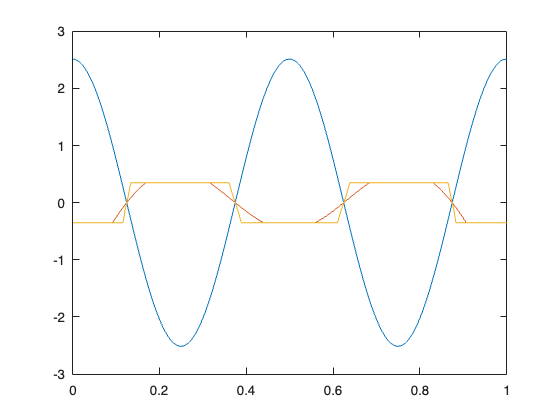


f2 = figure(2); f2.Theme = "Light";
plot(delta, normalforce)
xlabel('Indentation (mm)')
ylabel('Force (N)')

f3 = figure(3); f3.Theme = "Light";

plot(t, udotlat, t, tangentforce_1./normalforce, t, tangentforce_2./normalforce)

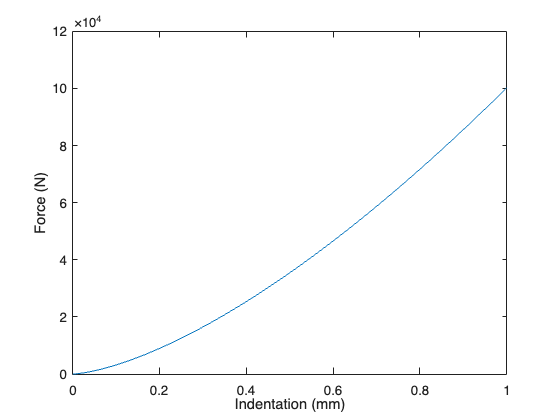


f4 = figure(4); f4.Theme = "Light";

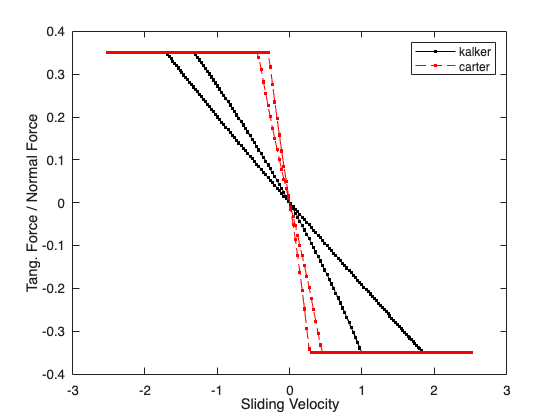

plot(udotlat, tangentforce_1./normalforce, 'k.-',....
    udotlat, tangentforce_2./normalforce, 'r.--')
legend('kalker', 'carter')
xlabel('Sliding Velocity')
ylabel('Tang. Force / Normal Force')